# Evaluating Trained YOLOv4 Model

In this script, we will now evaluate our parking signs detector. 

## Preparing the test data

% Loading the detector and the ground truth for the test images
load trained_yolov4_detector.mat detector
load parkingTestGT.mat parkingTestGT

% Creating a combined datastore of the images and bounding box data
[imds, blds] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imds, blds);

## **Running the detector on the test images**

We will first run the detector on the test images with a small confidence threshold. In the code below, we use 0.05. This means the detector is not picky and will return many detections, even if they have low confidence.

testResults = detect(detector, testData, "Threshold", 0.05)

testResults = 100×3 table
                    Boxes                        Scores            Labels      
    ______________________________________    ____________    _________________

    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {3×4 single                          }    {3×1 single}    {3×1 categorical}
    {0×4 single                          }    {0×1 single}    {0×1 categorical}
    {[184.3080 83.1856 120.5822 164.0099]}    {[  0.9636]}    {[EV           ]}
    {[168.8356 30.5025 151.8464 272.9999]}    {[  0.3363]}    {[EV           ]}
    {[ 307.3068 8.8403 141.6015 195.8080]}    {[  0.1329]}    {[EV           ]}
    {3×4 single                          }    {3×1 single}    {3×1 categorical}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {2×4 single                          }    {2×1 single}    {2×1 cate

## Visualizing detections

Select an image to view the detections (if any) and the associated scores. 

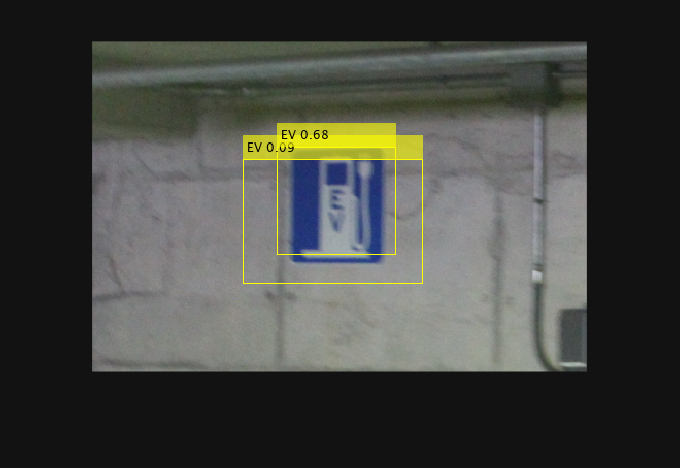

numImages = height(testResults);  % To set a limit on the control
imgIdx = 1;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

## Evaluating detection results

The `evaluateObjectDetection` function compares the detection results to the ground truth. The third input argument is the Intersection-over-Union (IoU) threshold used to define a true positive. The default value is 0.5. Here, we specify two IoU thresholds to show how a more strict location accuracy can impact the results. 

The output is an object containing the evaluation results. 

% Setting the IoU threshold. The default value is 0.5
iou = [0.25 0.5];

% Evaluating the detector
metrics = evaluateObjectDetection(testResults, testData, iou);

% Getting the class names to use later
classNames = metrics.ClassNames;

We will use the `summarize` function to create tables summarizing the results.

[datasetSummary, classSummary] = summarize(metrics)

datasetSummary = 1×4 table
    NumObjects    mAPOverlapAvg    mAP0.25    mAP0.5 
    __________    _____________    _______    _______

       135           0.51444       0.57902    0.44986


classSummary = 3×4 table
                  NumObjects    APOverlapAvg    AP0.25      AP0.5 
                  __________    ____________    _______    _______

    Accessible        48          0.43291       0.48752     0.3783
    Charger           29          0.27899       0.37991    0.17807
    EV                58          0.83142       0.86964     0.7932


## Visualizing precision-recall curves for different classes

The `precisionRecall` function returns cell arrays for the precision and recall values already sorted by descending confidence score. Each row is a different object class and each column corresponds to an IoU threshold used when evaluating the detection results. The third output is a cell array of detection confidence scores for each class.

[precision, recall, scores] = precisionRecall(metrics);

Use the drop-down menu to select a class and view the precision-recall curves for the two IoU thresholds.

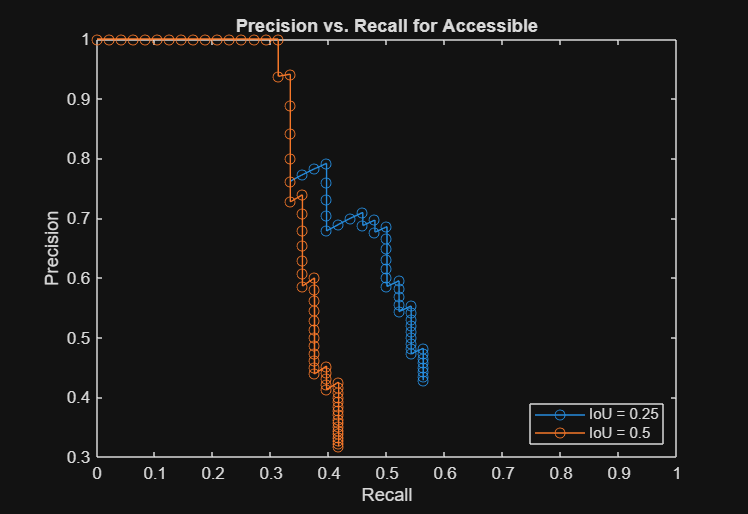

class = 1;
% Plot precision-recall for IoU 1
plot(recall{class,1}, precision{class,1}, "-o")
xlim([0 1])
xlabel("Recall")
ylabel("Precision")
title("Precision vs. Recall for " + classNames(class))
hold on
% Plot precision-recall for IoU 2
plot(recall{class,2}, precision{class,2}, "-o")
hold off
legend(["IoU = " + iou(1); "IoU = " + iou(2)], "Location", "southeast")

## Viewing the confusion matrix

A confusion matrix helps visualize the type of mistakes the model makes. Object detection models can leave objects unlabeled or assign labels to parts of the image with no ground truth objects. The label "unmatched" is used to identify true objects that were missed and detections that were not matched to any object. 

The `confusionMatrix` function returns a cell array that has the confusion matrix for each IoU threshold. The `confusionchart `function is used to view the results.

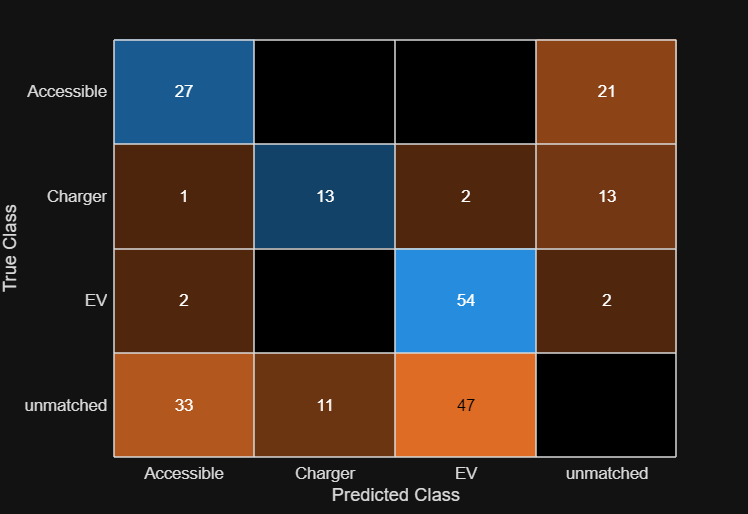

[cm, confusionClasses] = confusionMatrix(metrics);
confusionchart(cm{1}, confusionClasses)

## Choosing a detection threshold

We now need to find a global threshold that balances precision and recall across all classes. 

To find an appropriate threshold for the detector we will:

- Create a vector of threshold values to test 

- Run the detector with each threshold value

- Evaluate the detector with the `evaluateObjectDetection` function

- Use the `summarize` function to find the mAP

- Plot mAP vs. detection threshold to determine where mAP sharply decreases

% Vector of detection threshold values to test
thresholds = 0.1:0.1:0.9;

% Creating a vector to store the results
mAPs = zeros(length(thresholds),1);

% Creating a waitbar to monitor progress
f = waitbar(0);

% Looping through the detection thresholds, evaluating results, and saving the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    currentMetrics = evaluateObjectDetection(results, testData, iou);
    datasetSummary = summarize(currentMetrics);
    mAPs(ii) = datasetSummary{:, "mAP0.5"};
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

## Visualizing mAP vs detection threshold curve

Ideally, the curve will be relatively flat as you increase the detection threshold. This means that false positives are being suppressed without decreasing recall much. However, increasing the confidence threshold too much will reduce recall, significantly lowering the mAP.

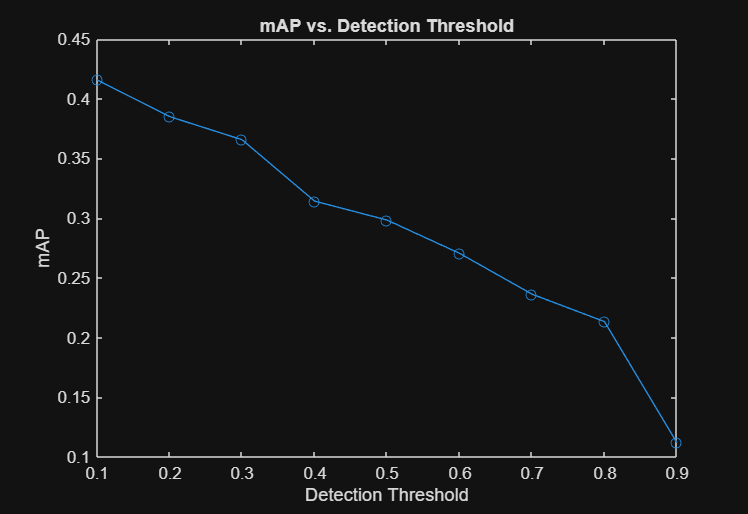

plot(thresholds, mAPs, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")